clc, clear, close all

% load vehicle parameters
veh = veh_params();
% addpath('..\c_generated_code\')

cd ..\
model = ocp_model_racecar();
cd sim\

x_s = model.x_s;
u_s = model.u_s;

x_min = model.x_min;
x_max = model.x_max;

% load nmpc parameters
N = model.N;
T = model.T; % time horizon length
Ts = model.Ts;

nx = model.nx;
nu = model.nu;
np = model.np;

% load racetrack
track_name = char("Catalunya");

racetrack_path = ['..\..\tro\tracks_race\' track_name '_race.csv'];
racetrack = readtable(racetrack_path);
xr = racetrack.x;
yr = racetrack.y;
sr = racetrack.s;
vr = racetrack.v;
phir = racetrack.phi;
kappar = racetrack.kappa;
wr = racetrack.wr;
wl = racetrack.wl;
index_max = calc_stop_flag([xr yr]);


% Initial values
n_s = model.x_s(7);
param_traj_0 = zeros(np*(N+1),1);
lbx_0 = repmat(model.x_min,(N-1),1);
ubx_0 = repmat(model.x_max,(N-1),1);
x_star_0 = zeros(nx,N+1);
u_star_0 = zeros(nu,N);

% V0 = 10/3.6;
V0 = 1;
s_star_0 = V0*(0:Ts:T)';
V_star_0 = V0*ones(N+1,1);
inputs_0 = zeros(nu,1);

% x = [v beta gamma wfl wfr wrl wrr X Y phi s]
omega_0 = V0/veh.rw;
x0 = [V0 0 0 omega_0 omega_0 omega_0 omega_0 xr(1) yr(1) phir(1) 0]';

Ts_log = Ts/2;
t_sim = 200;


out = sim("nmpc_sim.slx",t_sim);


if ~exist(fullfile(pwd,'simout'), 'dir')
   mkdir('simout')
end

out_file = ['simout\' 'out_' track_name];
save(out_file, 'out');

% figure,plot(out.x_next(:,9).*out.x_next(:,9)/(veh.Tb_s*veh.Tt_s))
track_tro_file = ['..\..\tro\tro_sol\' 'sol_' track_name];
load(track_tro_file)
fprintf(['dt laptime = ' num2str(out.t(end)-sol.t_opt(end))])

dt laptime = 1.4242

fprintf(['dten perctage = ' num2str((out.t(end)-sol.t_opt(end))/sol.t_opt(end)*100)])

dten perctage = 1.0167

fprintf(['RMS n = ' num2str(rms(out.n))])

RMS n = 0.085253

fprintf(['MAX n = ' num2str(max(abs(out.n)))])

MAX n = 0.26045

chi = (out.xi+out.beta_sim)*180/pi;
fprintf(['RMS chi = ' num2str(rms(chi))])

RMS chi = 0.32063

fprintf(['MAX chi = ' num2str(max(abs(chi)))])

MAX chi = 1.2146

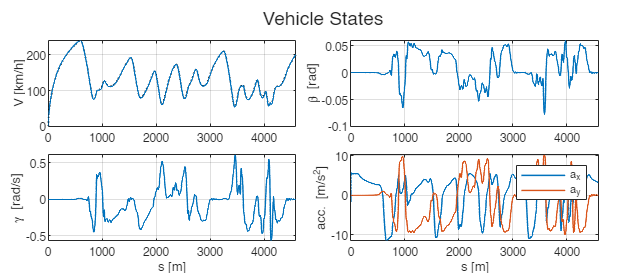

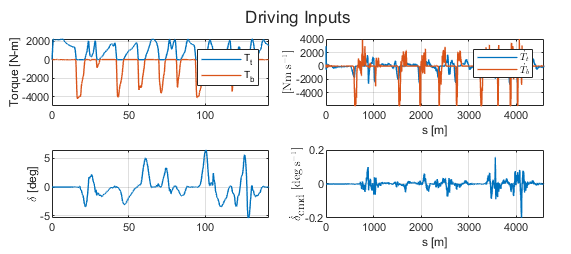

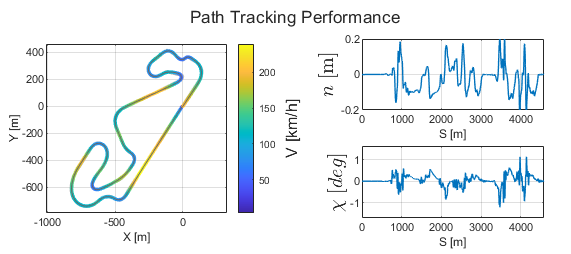

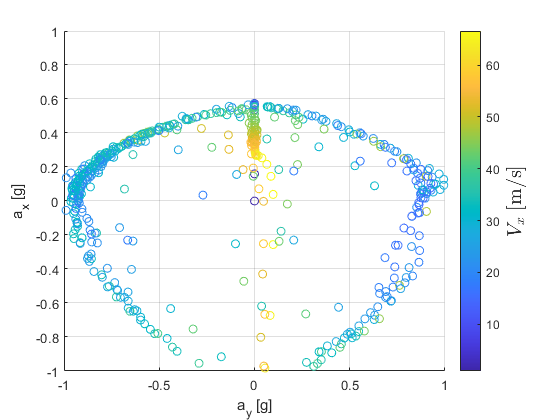

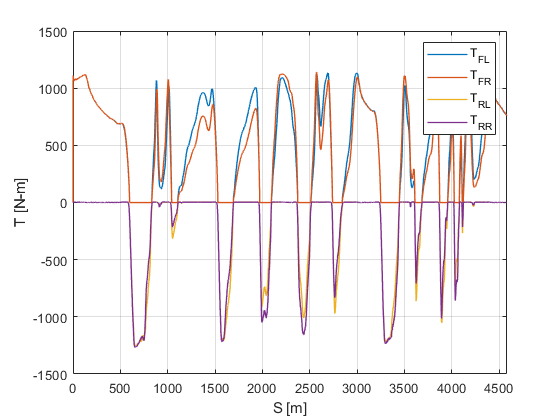

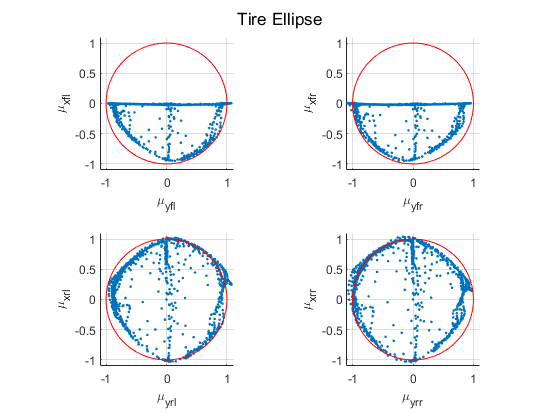

run("plot_sim_results.m")